clc; clearvars;

%% -------------------------
% Inputs
%% -------------------------
elev_angles_deg = 5:1:90;   % sweep from 5° to 90°
link_margin_dB = zeros(size(elev_angles_deg));  % to store results
range_km_arr = zeros(size(elev_angles_deg));
rec_power_dBW_arr = zeros(size(elev_angles_deg));
SNR_dB_arr = zeros(size(elev_angles_deg));
CNo_dBHz_arr = zeros(size(elev_angles_deg));
EbN0_dB_arr = zeros(size(elev_angles_deg));

altitude_km = 500;            % [km]
freq_mhz = 437;               % [MHz]

% CubeSat TX
tx_pwr_Watt = 1;              % [W]
tx_line_losses_dB = 1;        % [dB] TX cable/connector/filter losses
ant_gain_dBi = 0;             % [dBi] CubeSat antenna gain

% Path / propagation losses
sat_pointing_loss_dB = 0;     % [dB]
polarization_loss_dB = 0;     % [dB]
atm_attenuation_dB = 0;       % [dB]

% Ground Station RX
gs_ant_gain_dBi = 15;         % [dBi]
gs_pointing_loss_dB = 0.5;    % [dB]
gs_line_loss_dB = 1;          % [dB] RX cable/connector/filter losses
eff_noise_temp_K = 300;       % [K] system noise temperature

% Data link
data_rate_bps = 1000;         % [bps]
B_noise_Hz = 20e3;            % [Hz] receiver filter bandwidth
modulation_method = "BPSK";
EbN0_threshold_dB = 9.6;      % [dB] for target BER

%% -------------------------
% Derived parameters
%% -------------------------
% Transmit power in dBW
tx_pwr_dBW = 10*log10(tx_pwr_Watt);

% Satellite EIRP
sat_EIRP_dBW = tx_pwr_dBW - tx_line_losses_dB + ant_gain_dBi;

Re_km = 6371;  % Earth radius [km]

for i = 1:length(elev_angles_deg)
    elev_angle_degrees = elev_angles_deg(i);
    
    % Slant range
    range_km = sqrt((Re_km + altitude_km)^2 - Re_km^2 * cosd(elev_angle_degrees)^2) ...
           - Re_km * sind(elev_angle_degrees);
    range_m = range_km * 1e3;
    range_km_arr(i) = range_km;  % store

    % Free-space path loss
    lambda_m = 3e8 / (freq_mhz*1e6);
    free_space_loss_dB = 20*log10(4*pi*range_m / lambda_m);

    % Total path loss
    total_path_loss_dB = free_space_loss_dB + sat_pointing_loss_dB + ...
                         polarization_loss_dB + atm_attenuation_dB;

    % Received power (classic)
    rec_power_dBW = sat_EIRP_dBW - total_path_loss_dB + gs_ant_gain_dBi ...
                    - gs_pointing_loss_dB - gs_line_loss_dB;
    rec_power_dBW_arr(i) = rec_power_dBW;

    % Noise power (constant)
    k = 1.380649e-23;
    N_W = k * eff_noise_temp_K * B_noise_Hz;
    N_dBW = 10*log10(N_W);

    % SNR
    SNR_dB = rec_power_dBW - N_dBW;
    SNR_dB_arr(i) = SNR_dB;

    % G/T method
    G_rx_eff_dBi = gs_ant_gain_dBi - gs_pointing_loss_dB - gs_line_loss_dB;
    gs_figure_of_merit = G_rx_eff_dBi - 10*log10(eff_noise_temp_K);
    CNo_dBHz = sat_EIRP_dBW - total_path_loss_dB + gs_figure_of_merit + 228.6;
    CNo_dBHz_arr(i) = CNo_dBHz;

    EbN0_dB = CNo_dBHz - 10*log10(data_rate_bps);
    EbN0_dB_arr(i) = EbN0_dB;

    % Link margin
    link_margin_dB(i) = EbN0_dB - EbN0_threshold_dB;
end

% Simple display
disp('Elevation (deg) | Range (km) | Rec Power (dBW) | SNR (dB) | C/N0 (dBHz) | Eb/N0 (dB) | Link Margin (dB)');

Elevation (deg) | Range (km) | Rec Power (dBW) | SNR (dB) | C/N0 (dBHz) | Eb/N0 (dB) | Link Margin (dB)


for i = 1:length(elev_angles_deg)
    fprintf('%6.1f          | %8.2f    | %10.2f       | %6.2f  | %10.2f   | %6.2f    | %6.2f\n', ...
        elev_angles_deg(i), range_km_arr(i), rec_power_dBW_arr(i), ...
        SNR_dB_arr(i), CNo_dBHz_arr(i), EbN0_dB_arr(i), link_margin_dB(i));
end

   5.0          |  2077.09    |    -139.10       |  21.72  |      64.73   |  34.73    |  25.13
   6.0          |  1991.96    |    -138.74       |  22.08  |      65.09   |  35.09    |  25.49
   7.0          |  1911.29    |    -138.38       |  22.44  |      65.45   |  35.45    |  25.85
   8.0          |  1834.94    |    -138.02       |  22.79  |      65.80   |  35.80    |  26.20
   9.0          |  1762.76    |    -137.68       |  23.14  |      66.15   |  36.15    |  26.55
  10.0          |  1694.57    |    -137.33       |  23.49  |      66.50   |  36.50    |  26.90
  11.0          |  1630.19    |    -137.00       |  23.82  |      66.83   |  36.83    |  27.23
  12.0          |  1569.45    |    -136.67       |  24.15  |      67.16   |  37.16    |  27.56
  13.0          |  1512.16    |    -136.34       |  24.47  |      67.49   |  37.49    |  27.89
  14.0          |  1458.14    |    -136.03       |  24.79  |      67.80   |  37.80    |  28.20
  15.0          |  1407.20    |    -135.72       |

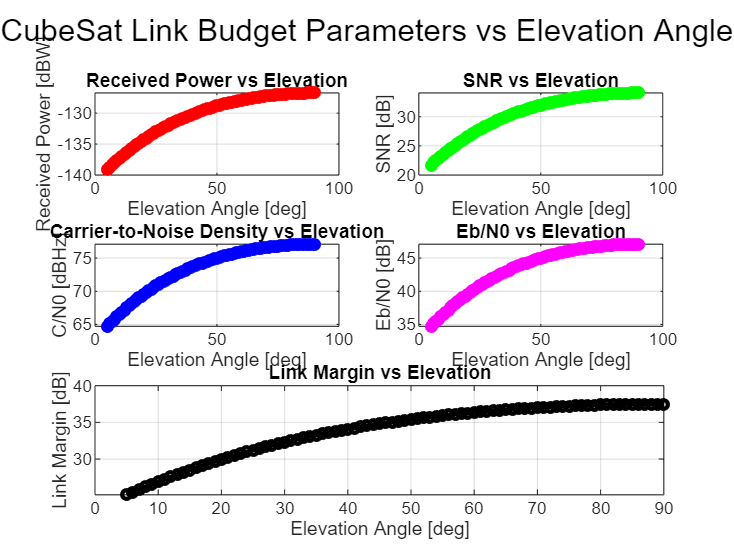


%% -------------------------
% Plot all link budget parameters vs elevation
%% -------------------------
figure;

subplot(3,2,1)
plot(elev_angles_deg, rec_power_dBW_arr, 'r-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Elevation Angle [deg]'); ylabel('Received Power [dBW]');
title('Received Power vs Elevation'); grid on;

subplot(3,2,2)
plot(elev_angles_deg, SNR_dB_arr, 'g-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Elevation Angle [deg]'); ylabel('SNR [dB]');
title('SNR vs Elevation'); grid on;

subplot(3,2,3)
plot(elev_angles_deg, CNo_dBHz_arr, 'b-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Elevation Angle [deg]'); ylabel('C/N0 [dBHz]');
title('Carrier-to-Noise Density vs Elevation'); grid on;

subplot(3,2,4)
plot(elev_angles_deg, EbN0_dB_arr, 'm-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Elevation Angle [deg]'); ylabel('Eb/N0 [dB]');
title('Eb/N0 vs Elevation'); grid on;

subplot(3,2,[5 6])
plot(elev_angles_deg, link_margin_dB, 'k-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Elevation Angle [deg]'); ylabel('Link Margin [dB]');
title('Link Margin vs Elevation'); grid on;

sgtitle('CubeSat Link Budget Parameters vs Elevation Angle');